# IMAGE PROCESSING OF DEWETTING FROM VIDEO 

Takes a ".avi" video file, creates a plot of normalized area vs time. Saves an "_Area.txt" file that stores the analyzed data and can be passed into the "dataprocessing" file for further processing and analysis.

% NOTE: this program requires Matlab "image processing toolbox" to run on Matlab 2020a/b

% Last tested: August 2020
% Version: Matlab 2020ab                    

% November 2020
% Vincent Xia

%TODO: fix edge algorithm; fix time output on _Area.txt

## Clear everything

close all hidden;
clc;

## Input dialogs

Analysis settings:

[file,path] = uigetfile('*.avi'); %choose .avi file (can change format if needed)
file_name = strcat(path,file); % gets file name from uigetfile

analysis_settings = inputdlg({'Remove objects smaller than X pixels 100-1000', ... % will not designate pixels smaller than 'X' as wet/dry (reduces variation)
                                'Skip Frames [1-1000]',... % # of frames skipped between each frame analysis (larger number = faster)
                                'Initial frame above surface',... % first frame where dome is exposed 
                                'Select video frame for area analysis'},'Sample',...  % Frame for defining total area; pick frame after edge 'gravity-driven' dewetting occurs, and once interference patterns begin                                                            
                                [1 50; 1 20;1 20;1 20],{'250','3','40','2500'});

Analysis types:                                 

analysis_type = inputdlg({'New or old software?(1=New,0=Old)',... % Old uEye Cockpit laptop software or New Thorcam software from 2/25/2020 onwards
                          'Lubricin or Water?(1=lubricin, 0=water)',... % Which sample are you measuring dewetting on?
                          'Circle or freehand area fit? (1=circle, 0=freehand)'},... % the area selection method for defining total area
                          'Analysis Type', [1 40; 1 40; 1 40], {'1','1','1'});                                 

Video output types:

video_output_types = inputdlg({ 'Falsecolor final output? (1=no, 0=yes) ',... % makes a falsecolor overlay of the binary mask on the original frame          
                          'Output analyzed frames?(1=no, 0=yes)',... % makes a copy of the analyzed frames from the original video
                          'Output individual masks video?(1=no, 0=yes)',... % makes a montage copy of the individual masks for debugging purposes
                          'Output black/white mask?(1=no,0=yes)',... % binary version of final mask
                          'Output animated plot? (1=no, 0=yes)'},... % animated video of the dewetting plot
                          'Output video types (note: choosing yes on any of these will be slower)', [1 40; 1 40; 1 40; 1 40; 1 40], {'1','1','1','1','1'});

## Parameters for image processing

Initialize our parameters from the dialog boxes:

[remove_Pixels,skip_frame,t0_frame_num,area_frame_num,background_frame_num,...
    sftwre_type,liquid_type,area_fit_type,...
    output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,output_animated_plot] = fill_params(analysis_settings,analysis_type,video_output_types); %fill in all the parameters from the dialog boxes using helper function

Theshold values for hue, saturation, value analysis (use Threshold Check or Matlab "Color Thresholder" App to test values)

if sftwre_type == 0  %Old uEye Cockpit software
    if liquid_type == 1 %DI water
        % Used "DIWater HPL3 RT2" file from 2-21-2020, frame 1000 to obtain
        % threshold values  
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;   
    elseif liquid_type == 0 %lubricin    
        %Used ".5 ugml lubricin DS HPL 2 37C 1" from 1-20-2020,frame 2085
        %to obtain threshold values
        hueThresholdLow = .4;
        hueThresholdHigh = .5;
        saturationThresholdLow = .3;
        saturationThresholdHigh = .4;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;
    end
elseif sftwre_type == 1 %New Thorcam software
    if liquid_type == 0 %DI Water

        % From 07-05-20 HPL3 DIWater Test 2 file
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.659;
        valueThresholdHigh = 1;
        
    elseif liquid_type == 1 %lubricin
        
  %      For 08-12-20 1 ugmL HPL3 RT solvent trap
%         hueThresholdLow = .438;
%         hueThresholdHigh = .535;
%         saturationThresholdLow = .177;
%         saturationThresholdHigh = .236;
%         valueThresholdLow = .718;
%         valueThresholdHigh = .906;

        
    % For 07-19-20 .5 ugmL HPL1 NR (less discriminatory)
%         hueThresholdLow = .410;
%         hueThresholdHigh = .554;
%         saturationThresholdLow = .104;
%         saturationThresholdHigh = .271;
%         valueThresholdLow = .439;
%         valueThresholdHigh = .780;
        
        
        % For 10-13-20 1 ugmL lubricin TS HPL4 37C
        hueThresholdLow = .422;
        hueThresholdHigh = .500;
        saturationThresholdLow = .104; %.164 <--- saturation boundaries have a substantial impact on video thresholding!
        saturationThresholdHigh = .271; %.233
        valueThresholdLow = .490; %.490
        valueThresholdHigh = .761; %.761
    end 
end

## Video Import

video=VideoReader(file_name); % starts reading video
file_name=file_name(1:end-4); % removes .avi or other file extension from filename
num_frames=video.NumFrames; % gets # of frames in video
input_fps=video.FrameRate; % gets frames/second in initial video
vidHeight = video.Height; % gets video height
vidWidth = video.Width; % gets video width
background_frame = read(video, background_frame_num); %gets background frame in video (used for deleting background). background frame is when dome crosses interface
background_frame_cropped = imcrop(rgb2gray(background_frame),[0,0,1024,768]); % Converts to grayscale and crops size                                                                              

## Set total area

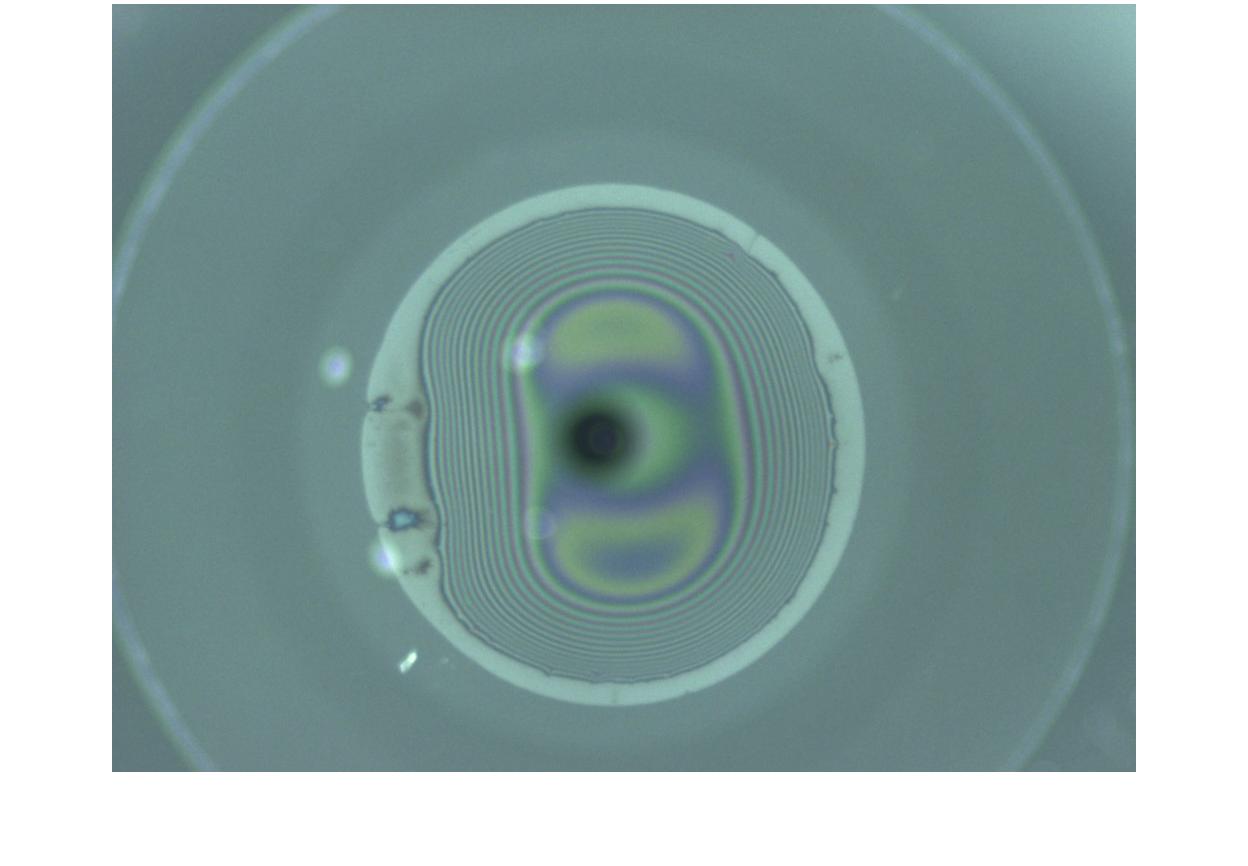

totalareaframe        = read(video,area_frame_num);                % Read user specified frame for area analysis
totalareaframecropped = imcrop(totalareaframe,[0,0,1024,768]);     % Crop area frame
totalareaframegray    = rgb2gray(totalareaframecropped);           % Grayscale area frame

[mask, max_area, shadowMask, camera_area, totalAreaCenter, totalAreaRadius] = userdraw_ROI(totalareaframecropped,area_fit_type); %helper function to handle our ROI drawing

## Analyze video

% Define output video parameters; open videos for writing
output_framerate = 20; %output frame rate
[bw_vid, analyzed_frames_vid, all_masks_vid, false_color_vid] = initVids(output_black_white_mask, file_name, output_framerate, output_analyzed_frames, output_all_masks, output_false_color);

% Begin video processing
wait_bar = waitbar(0,'Analyzing... Go grab a cup of coffee...');
num_iterations = floor(num_frames/skip_frame); %number of times we iterate through the analysis loop

dewet_area = zeros(1,num_iterations*skip_frame); % stores the area for every frame index (formerly called 'grain_areas')
wet_area = zeros(size(dewet_area)); % stores normalized wet area for every frame index

final_frame_num = num_frames; % dictates the last frame of the video to be analyzed
for cur_frame_num=t0_frame_num: skip_frame: final_frame_num
    waitbar(cur_frame_num/final_frame_num,wait_bar); % update wait bar to show analysis progress
    orig_frame=read(video,cur_frame_num); % reading individual frames from input video
    crop_frame=imcrop(orig_frame,[0,0,1024,768]); 
    gray_frame=rgb2gray(crop_frame); % grayscale frame from video
    subtract_frame=gray_frame - background_frame_cropped; % Subtract background frame from current frame

### Masking and binarization: 

    subtract_frame(shadowMask) = 0; %clear every subtract_frame pixel inside the shadowMask | applies the camera mask
    subtract_frame(~mask) = 0; %apply area mask
    bw_frame_mask=imbinarize(subtract_frame);

Area mask

    bw_frame_mask_clean = bwareaopen(bw_frame_mask, remove_Pixels); % remove connected objects that are smaller than 250 pixels in size
    bw_frame_mask_clean = ~bwareaopen(~bw_frame_mask_clean, remove_Pixels); % remove holes that are smaller than 20 pixels in size

HSV Masking

    hsv_frame=rgb2hsv(crop_frame); % convert to hsv image
    hsv_frame(shadowMask) = 0; % apply camera mask
    hsv_frame(~mask) = 0; % apply area mask
    
    % Apply each color band's particular thresholds to the color band
	hueMask = (hsv_frame(:,:,1) >= hueThresholdLow) & (hsv_frame(:,:,1) <= hueThresholdHigh); %makes mask of the hue image within theshold values
	saturationMask = (hsv_frame(:,:,2) >= saturationThresholdLow) & (hsv_frame(:,:,2) <= saturationThresholdHigh); %makes mask of the saturation image within theshold values
	valueMask = (hsv_frame(:,:,3) >= valueThresholdLow) & (hsv_frame(:,:,3) <= valueThresholdHigh); %makes mask of the value image within theshold values
    
    HSV_mask = hueMask & saturationMask & valueMask; % defines area that fits within hue mask, saturation mask, and value mask    
    
    % Fill in the holes of the mask 
	HSV_mask_rmv_maskHoles = ~bwareaopen(~HSV_mask, remove_Pixels);
    
    % Filter out small objects.
    HSV_mask_rmv_obj = bwareaopen(HSV_mask_rmv_maskHoles, remove_Pixels); %fill in holes smaller than 250 pixels in size
    
    % apply binarization mask
    HSV_bw_mask = HSV_mask_rmv_obj & bw_frame_mask_clean;


Count Area; use** Edge Algorithm 2 **to throw away inside regions

 
    [final_mask, dewet_area(cur_frame_num)] = countArea(HSV_bw_mask,totalAreaRadius,gray_frame,totalAreaCenter);      
    

Write final videos  

        % Only write video after dome has crossed the interface (i.e., background frame)
        final_mask = im2uint8(final_mask~=0); % convert mask
        
        wet_area(cur_frame_num) = writeOutputVids(output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,...
                                                          gray_frame,crop_frame,orig_frame,HSV_mask,HSV_mask_rmv_obj,bw_frame_mask_clean,final_mask,...
                                                          bw_vid,false_color_vid,analyzed_frames_vid,all_masks_vid,...
                                                          dewet_area(cur_frame_num),...
                                                          t0_frame_num,cur_frame_num,...
                                                          max_area,camera_area,...
                                                          input_fps);
    
end

closeVids(output_black_white_mask, bw_vid, output_analyzed_frames, analyzed_frames_vid, output_all_masks, all_masks_vid, output_false_color, false_color_vid);
close(wait_bar); %closes wait bar

## Generate time vs area; plot data; write animated video

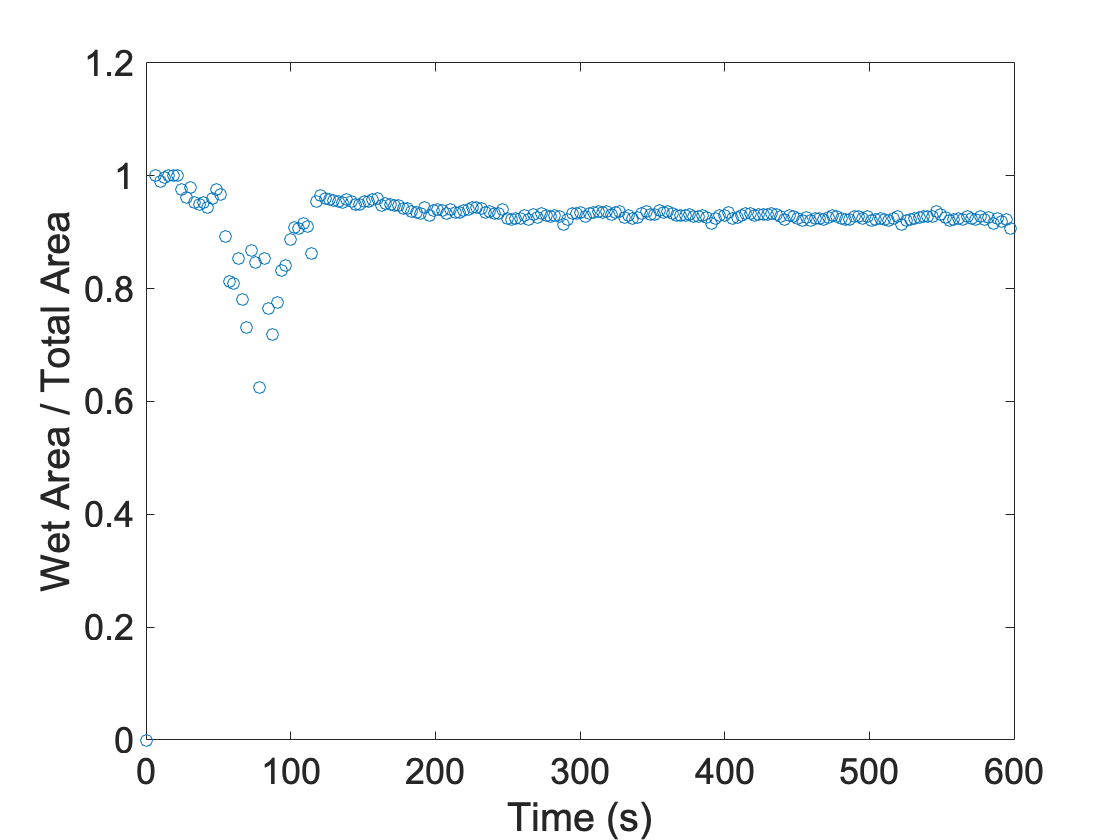

%Create time array
time = zeros(1,length(wet_area)); % initialize time
output_size = floor(final_frame_num/skip_frame); % number of row entries for the final area+time file output
area_data_output = zeros(2,output_size); % 2D matrix storing the corresponding area+time output

if(~output_animated_plot) % initialize video of animated plot
    animated_vid=VideoWriter(strcat(file_name,'_plot'),'MPEG-4');
    animated_vid.FrameRate = output_framerate;
    open(animated_vid);
end

figure;
hold on;
formatAreaPlot(); % Create and format area plot

for cur_frame_num = t0_frame_num:skip_frame:final_frame_num
    time(cur_frame_num)=cur_frame_num/input_fps; %adjusts time for skipped frames and initial frame rate
    entry_num = (cur_frame_num-t0_frame_num)/skip_frame + 1; % row entry number for the data output file
    area_data_output(:,entry_num) = [time(cur_frame_num); wet_area(cur_frame_num)];
    
    if(~output_animated_plot) % writes video of animated plot for each 
        plot(time(cur_frame_num),wet_area(cur_frame_num),'o');
        writeVideo(animated_vid,getframe(gcf));
    end
end

if(~output_animated_plot)
   close(animated_vid);
end


plot(time,wet_area,'o'); % generate plot
print('-dtiff',strcat(file_name,'_graph.tiff')); %save to tiff file

## Store analyzed data into text file to be used with image processing code

file_id=fopen(strcat(file_name,'_Area.txt'),'w');
fprintf(file_id,'%15s %15s\r\n','time after t0 (sec)','area'); 
fprintf(file_id, '%15.3f %15.3f \n', area_data_output);
fclose(file_id);

## Store all data (including skipped frames) into text file

file_id=fopen(strcat(file_name,'_AllData.txt'),'w');
fprintf(file_id, '%d %d \n', [time wet_area]');
fclose(file_id);

## Store image processing parameters into text file

file_id=fopen(strcat(file_name,'_Parameters.txt'),'w'); %saves parameters used in file for analysis 
fprintf(file_id, 'remove_Pixels = %d \n', remove_Pixels);
fprintf(file_id, 't_0 = %d \n', t0_frame_num);
fprintf(file_id, 'background = %d \n', background_frame_num);
fprintf(file_id, 'frame for area analysis = %d \n', area_frame_num);
fprintf(file_id, 'frames_skipped = %d \n', skip_frame);
fprintf(file_id, 'HueThreshold = (%.3f,%.3f) \n', hueThresholdLow, hueThresholdHigh);
fprintf(file_id, 'SaturationThreshold = (%.3f,%.3f) \n', saturationThresholdLow, saturationThresholdHigh);
fprintf(file_id, 'ValueThreshold = (%.3f,%.3f)', valueThresholdLow, valueThresholdHigh);
fclose(file_id);

# Helper functions

Initialize parameters from dialog boxes:

function [remove_Pixels,skip_frame,t0_frame_num,area_frame,background_frame_num,...
            sftwre_type,liquid_type,areaFitType,...
            output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,output_animated_plot] = fill_params(input_dialog,analysis_type,video_output_types)

    remove_Pixels = str2double(input_dialog{1}); % parameter passed to 'bwareaopen' that tells us how small (in pixels) objects need to be before we remove them from the analysis
    skip_frame = str2double(input_dialog{2}); %frequency with which we analyze video frames
    t0_frame_num=str2double(input_dialog{3});  % intial time when the dome reaches its maximum height
    area_frame=str2double(input_dialog{4}); % Background frame for defining total area; pick frame 
                                            % after edge 'gravity-driven' dewetting occurs, and once
                                            % interference patterns begin
                                                                                  
    background_frame_num = t0_frame_num+5; % Keep at t_0 for videos with fast dewetting
    
    sftwre_type = str2double(analysis_type{1}); % from analysis_type input dialog
    liquid_type = str2double(analysis_type{2}); % from analysis_type input dialog
    areaFitType = str2double(analysis_type{3}); %use an assisted freehand on the area_frame fitting, or just use a circle

    output_false_color = str2double(video_output_types{1}); % print the final binary mask output video in BW or falsecolor overlay on original frame
    output_analyzed_frames = str2double(video_output_types{2}); % tells us whether or not to print an mp4 of analyzed frames from original video
    output_all_masks = str2double(video_output_types{3}); % tells us whether or not to print an mp4 of individual masks from video
    output_black_white_mask = str2double(video_output_types{4}); % simple black/white mask mp4 video
    output_animated_plot=str2double(video_output_types{5}); % should we plot the animated video or not?
    
end

Highest level helper function to allow user to draw the ROI

function [mask, max_area, shadowMask, camera_area, center, radius] = userdraw_ROI(totalareaframecropped,areaFitType)
    %set the total area mask
    roi = showAreaROI(totalareaframecropped,areaFitType); %show the frame and return an roi that we can calculate things from
    if (areaFitType == 1)
        center = roi.Center;
        radius = roi.Radius;
    else 
        mask = createMask(roi);
        stats = regionprops('table',mask,'Centroid','MajorAxisLength','MinorAxisLength'); % estimate the center and radius for the drawn region
            center = stats.Centroid;
            diameter = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
            radius = diameter/2;
    end
    mask = createMask(roi);
    max_area = nnz(mask);     

    %set the camera shadow area
    shadowROI = showShadowROI(totalareaframecropped);    
    shadowMask = createMask(shadowROI);
    camera_area = nnz(shadowMask); 
    
    close;
end

Mid-level helper function to show the freehand or circle ROI

function [roi] = showAreaROI(totalareaframecropped,areaFitType)
    imshow(totalareaframecropped);                                 % Show area frame as total area input
    
    if (areaFitType == 1)
        xlabel('Draw circle around total area, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
        roi = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
    else
        xlabel('Draw freehand around total area; double-click to close and double-click again to finish','FontSize',16,'FontName','Arial');
        roi = drawassisted('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
        while (isempty(roi.Position)) % repeat if the user deletes the ROI
            roi = drawassisted('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
        end
    end
    customWait(roi); % wait for double click
end

function [shadowROI] = showShadowROI(totalareaframecropped)
    imshow(totalareaframecropped);                                 % Show area frame as total area input
    xlabel('Draw circle around camera shadow, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
    shadowROI = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");

    customWait(shadowROI);
end

Use a custom wait function to block the MATLAB command line while you interact with the rectangle. This example specifies a function called `customWait` (defined at the end of the example). While the command line is blocked, resize and reposition the rectangle so that it encompasses one pear. Double-click on the circle to resume execution of the `customWait` function. This is the custom wait function that blocks the program execution when you click an ROI. When you have finished interacting with the ROI, the function returns the position of the ROI. 

function customWait(hROI) %general wait function
    l = addlistener(hROI,'ROIClicked',@clickCallback); % Listen for mouse clicks on the ROI
    uiwait; % Block program execution
    delete(l); % Remove listener
end


This click callback function resumes program execution when you double-click the ROI. Note that event data is passed to the callback function as an [`images.roi.ROIClickedEventData`](docid:images_ref.mw_81029a52-9470-4901-a436-7fd4180ba6a7) object, which enables you to define callback functions that respond to different types of actions. For example, you could define a callback function to resume program execution when you click the ROI while pressing the Shift key or when you click a specific part of the ROI such as the label.

function clickCallback(~,evt)
    if strcmp(evt.SelectionType,'double')
        uiresume;
    end
end

Circle specific custom wait function

function [center, radius] = customWaitCircle(hROI)
    l = addlistener(hROI,'ROIClicked',@clickCallback);  % Listen for mouse clicks on the ROI
    
    uiwait; % Block program execution
    
    delete(l); % Remove listener
    
    % Return the circle's center and radius
    center = hROI.Center;
    radius = hROI.Radius;
end

### Count area 

calculate the dewetted area array using the provided mask and 'edge algorithm 2'

function [labelImg, area] = countArea(coloredObjectsMask,totalAreaRadius,gray_frame,totalAreaCenter)

    connected_components = bwconncomp(coloredObjectsMask,8); % finds connected components within binary image (connectivity of 4)                
    num_components = size(connected_components.PixelIdxList); % number of connected components found by 'bwconncomp'
    
    radiusRmv = totalAreaRadius - 10; % radius for our clearing region. The center lies at the center of our 'totalArea' circle
                
    if (~num_components) % if there's at least one connected component
        for idx = 1:num_components % for each component in connComp
            [row,col] = ind2sub(size(gray_frame), connected_components.PixelIdxList{1,idx});
            coord = cat(2,col,row); % pixel coordinate
            
            loc = (coord(:,1) - totalAreaCenter(1)).^2 + (coord(:,2) - totalAreaCenter(2)).^2;
                       
            if ~any(loc > radiusRmv^2) % if any pixels in the connected component fall outside our clearing region, with radius 'radiusRmv'...   
                coloredObjectsMask(connected_components.PixelIdxList{1,idx}) = 0; % if the component falls entirely inside our clearing region, set pixels to 0 (black)
            end                                  
        end
    end
    
    connCompClean = bwconncomp(coloredObjectsMask); % finds connected components again, since now we've removed objects in our clearing region
    labelImg = labelmatrix(connCompClean); % creates labeled matrix from bwconncomp structure
    
    graindata = regionprops(connCompClean, 'Area'); % computes 'Area' measurement of connCompClean
    
    area = sum([graindata.Area]); % sum of areas in our cleaned connected components to be used when calculating wet vs dry area   
    %return area
    

end


**Write videos**

writes the output videos for a given frame based on user-specified output types

function [wet_area] = writeOutputVids(outputFalseColor,outputAnalyze,outputMasks,output_black_white_mask,...
                              gray_frame,crop_frame,orig_frame,HSV_mask,HSV_mask_rmv_obj,bw_frame_mask_clean,finalMask, ...
                              output_vid,falseColorVideo,analyzedVideo,allMasksVideo, ...
                              dewet_area,...
                              t0_frame_num,cur_frame_num,...
                              max_area,camera_area,...
                              input_fps)

        vid_time = cur_frame_num/input_fps; % raw video time
        graph_time = vid_time - t0_frame_num/input_fps; % adjusts time for skipped frames and initial frame rate  
        wet_area = 1-(dewet_area./(max_area-camera_area)); % normalize dry area based on total area minus camera shadow area. subtract from 1 to get total wet area            

        frame_info = sprintf('Frame: %d | Video time: %.3f sec | Graph time: %.3f sec | Area: %.3f', cur_frame_num, vid_time, graph_time, wet_area); % prints frame #, time stamp, and area for each mp4 video frame


Output black & white mask video:

        if (~output_black_white_mask) % make a movie of the black/white final mask frames               
            output_text = insertText(finalMask,[100 50],frame_info,'AnchorPoint','LeftBottom'); % requires Matlab Computer Vision Toolbox            
            writeVideo(output_vid,output_text); % writes video with analyzed frames  
        end

Output falsecolor:        

        if (~outputFalseColor)  % make a falsecolor overlay of our final mask over the original grayscale image 
            FinalImgFuse = imfuse(finalMask,gray_frame,'falsecolor','Scaling','joint','ColorChannels',[1 2 0]); %create falsecolor overlay of binary mask over original image    
            falseColorInfo = sprintf('red = binary mask | green = original img | yellow = both'); % prints false color info                
            output_text = insertText(FinalImgFuse,[100 50],frame_info,'AnchorPoint','LeftBottom','BoxColor','black',"TextColor","white"); % NOTE: requires Matlab Computer Vision Toolbox
            output_text = insertText(output_text,[100 100],falseColorInfo,'AnchorPoint','LeftBottom','BoxColor','black',"TextColor","white"); % NOTE: requires Matlab Computer Vision Toolbox    
            writeVideo(falseColorVideo,output_text); %writes video with analyzed frames
        end        

Output analyzed frames:

        if (~outputAnalyze) 
            frame_info = sprintf('Frame: %d | Time: %.3f sec ', cur_frame_num , graph_time); % prints frame #, time stamp, and area for each mp4 frame
            image = insertText(orig_frame,[30 725],frame_info,'FontSize',55,'BoxColor','white','AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(analyzedVideo,image);
        end

Output individual masks:       

        if(~outputMasks) 
            box_color = 'green';
           
            im0 = insertText(crop_frame,[100 50],"orig image",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im1 = insertText(im2uint8(HSV_mask),[100 50],"HSV mask",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
                fuse = imfuse(im2uint8(HSV_mask),im2uint8(bw_frame_mask_clean),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]); %create falsecolor overlay of area mask with HSV mask
            im2 = insertText(fuse, [100 50],'HSV w/ binarize overlay','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im3 = insertText(im2uint8(bw_frame_mask_clean),[100 50],"Binarize mask (contains area mask)",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');            
            im6 = insertText(finalMask,[100 50],'final mask','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            
            im7 = insertText(im2uint8(HSV_mask_rmv_obj),[100 50],"HSV mask after removing small objects and small mask holes",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            
%           blank = zeros(size(im0)); use this to fill in gaps of the montage if there's not enough videos to output
            concat1 = cat(1,im0,im1,im2); %concatenate the images together
            concat2 = cat(1,im3,im6,im7);
            concatFinal = cat(2,concat1,concat2);
            
            finalImage = insertText(concatFinal,[300 50],frame_info,'FontSize',20,'AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(allMasksVideo,finalImage);
        end     
end

        

Formatting specs for area plot:

function formatAreaPlot() 
    xlim([0 600]);
    ylim([0 1.2]);
    xlabel('Time (s)','FontSize' , 28,'FontName'   , 'Arial');
    ylabel('Wet Area / Total Area','FontSize' , 20,'FontName'   , 'Arial');
    set(gca,'FontName', 'Arial','FontSize',18);
    set(gcf, 'PaperPositionMode', 'auto');
    box on;
end


Initializing and open output videos

function [bw_vid, analyzed_frames_vid, all_masks_vid, false_color_vid] = initVids(output_black_white_mask, file_name, output_framerate, output_analyzed_frames, output_all_masks, output_false_color)
    bw_vid = 0; %initialize videos
    analyzed_frames_vid = 0;
    all_masks_vid = 0;
    false_color_vid = 0;

    if (~output_black_white_mask)
        bw_vid=VideoWriter(strcat(file_name,'_maskVideo'),'MPEG-4'); %writes black/white video showing wet area (black) vs. dry area (white)
        bw_vid.FrameRate = output_framerate; %sets output video frame rate
        open(bw_vid); % opens output video for writing
    end
    
    if (~output_analyzed_frames) 
        analyzed_frames_vid = VideoWriter(strcat(file_name,'_analyzedOrigVideo'),'MPEG-4'); %writes video showing the original frames that were analyzed
        analyzed_frames_vid.FrameRate = output_framerate; %sets output video frame rate
        open(analyzed_frames_vid); % opens video for analyzed frames from original video
    end
    if (~output_all_masks)
        all_masks_vid = VideoWriter(strcat(file_name,'_allMasks'),'MPEG-4'); %writes video showing the original frames that were analyzed
        all_masks_vid.FrameRate = output_framerate; %sets output video frame rate
        open(all_masks_vid); % opens video for displaying individual masks
    end
    if (~output_false_color)
        false_color_vid = VideoWriter(strcat(file_name,'_falseColor'),'MPEG-4'); %writes falsecolor video showing wet area (green) and analyzed dry area (red)
        false_color_vid.FrameRate = output_framerate; %sets output video frame rate
        open(false_color_vid); % opens false color overlay video
    end
end


Close output videos


function closeVids(output_black_white_mask, bw_vid, output_analyzed_frames, analyzed_frames_vid, output_all_masks, all_masks_vid, output_false_color, false_color_vid)
    if (~output_black_white_mask)
        close(bw_vid); %close videowriter for binary mask
    end
    if (~output_analyzed_frames)
        close(analyzed_frames_vid); %close analyzed frames video
    end
    if(~output_all_masks)
        close(all_masks_vid); %close individual masks video
    end
    if (~output_false_color)
        close(false_color_vid); %close falsecolor video
    end
end